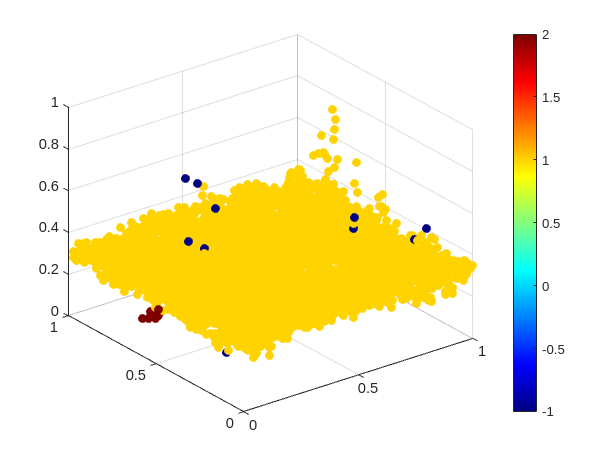

i = 1

i = 39

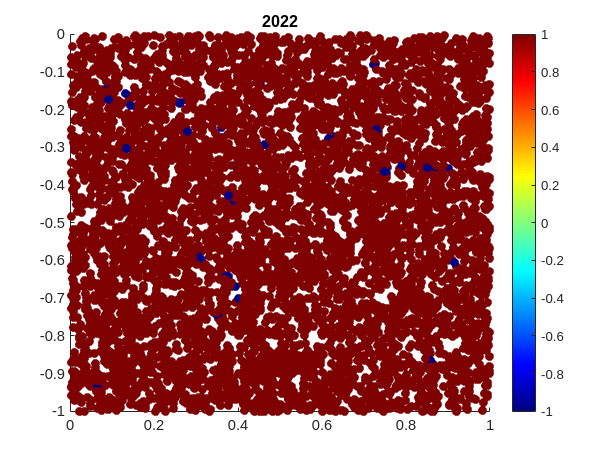

clf
n = 39;
img = imread('images/alberta/mining_1984.png');
imsize = size(img);
imsize(4) = n;
ims = ones(imsize);
for i=[1 39]
    i
    % ims(:,:,:,i) = imread('images/alberta/mining_' + string(1983+i) + '.png');

    im = imread('images/alberta/mining_' + string(1983+i) + '.png');
    img = imresize(im, 0.5);
    img = im2double(img);
    
    hsv = rgb2hsv(img);
    h = hsv(:,:,1);
    h = reshape(h.',1,[]);
    s = hsv(:,:,2);
    s = reshape(s.',1,[]);
    v = hsv(:,:,3);
    v = reshape(v.',1,[]);
    x = 1:length(img);
    x = repmat(x, length(img(:,1)), 1);
    x = reshape(x.',1,[]);
    y = transpose(1:length(img(:,1)));
    y = repmat(y, 1, length(img));
    y = reshape(y.',1,[]);
    
    h_scale = h/max(h);
    s_scale = s/max(s);
    v_scale = v/max(v);
    x_scale = x/max(x);
    y_scale = y/max(y);
    
    data = [2*h_scale; s_scale; 2*v_scale; x_scale; y_scale]';

    [idx, corepts] = dbscan(data, 0.15, 100); % 0.1 30
    % scatter3(h_scale, s_scale, v_scale)
    scatter3(y_scale, x_scale, v_scale, [], idx, 'filled')
    colorbar
    colormap jet
    scatter(x_scale, -y_scale, [], idx, 'filled')
    title(string(1983+i))
    colorbar
    colormap jet
end